addpath("MDC/");
addpath("DETEST/");
addpath("Final Lab/CODES/");

This is the final project of the stat methods where we search for a signal in some data. First I will look at the training data.

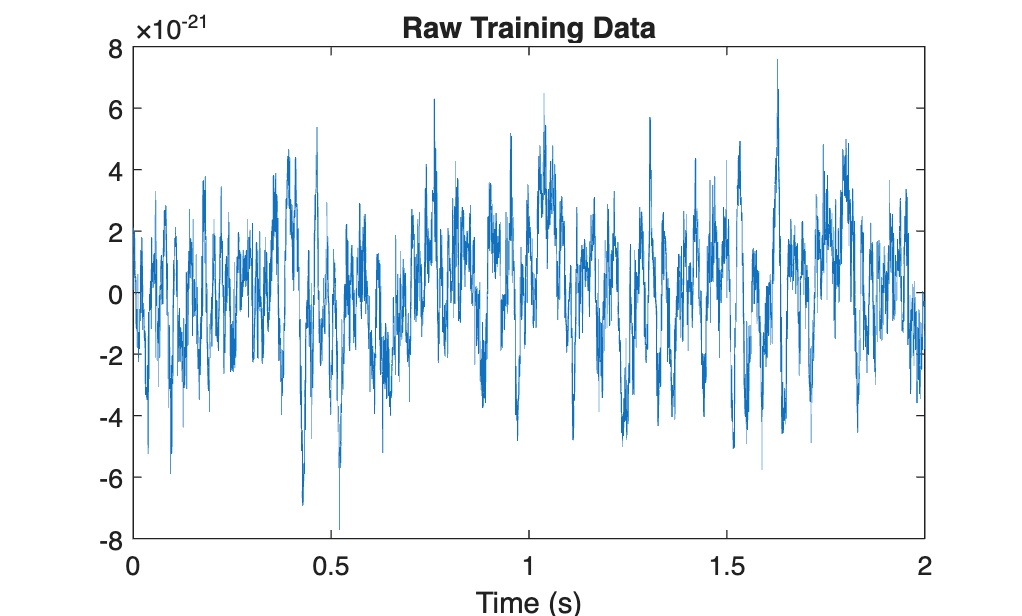

training = load("MDC/TrainingData.mat");
% training is a struct containing data and sampFreq
dt = 1/training.sampFreq;
datalentrain = length(training.trainData)/training.sampFreq;
timeVector = 0:dt:datalentrain-dt;
idx = timeVector <= 2; % plotting two seconds to compare to analysis data
figure;
plot(timeVector(idx),training.trainData(idx)); % look at the raw training data
xlabel('Time (s)');
title('Raw Training Data');

The next thing we'll do is generate the periodgram and generate the PSD. 

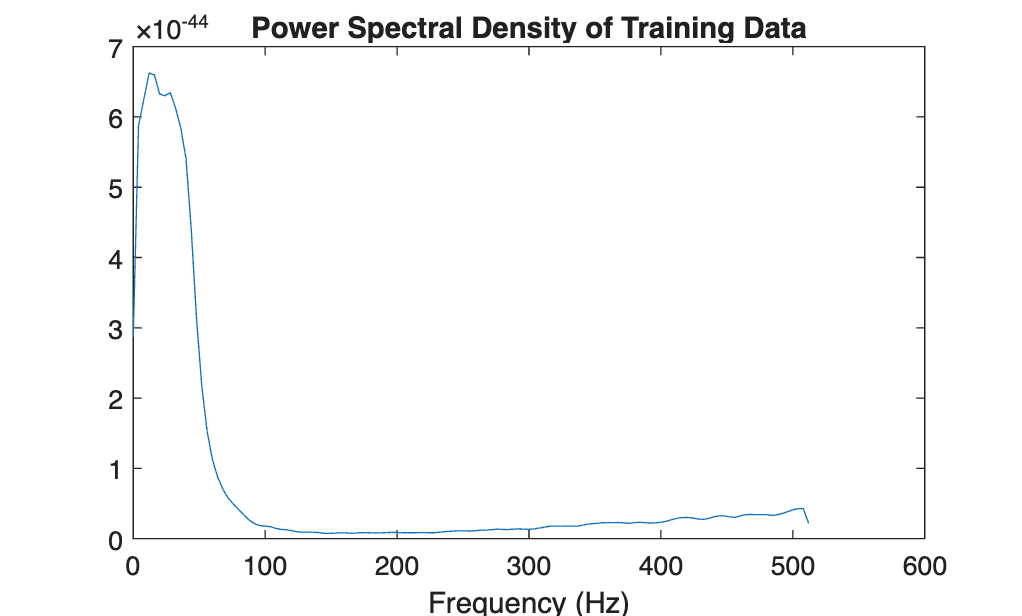

[ppx,f] = pwelch(training.trainData, 128, [], [], training.sampFreq);
noisePSD = @(freq) interp1(f, ppx, freq, 'linear', 'extrap');
figure;
plot(f,ppx);
xlabel('Frequency (Hz)');
title('Power Spectral Density of Training Data');

The PSD looks like a partial gaussian with a long tail at highter frequencies. 

Next I will start to look at the analysis data.

analysis = load("MDC/analysisData.mat");
dt = 1/training.sampFreq

dt = 9.7656e-04

datalen = length(analysis.dataVec)/training.sampFreq

datalen = 2

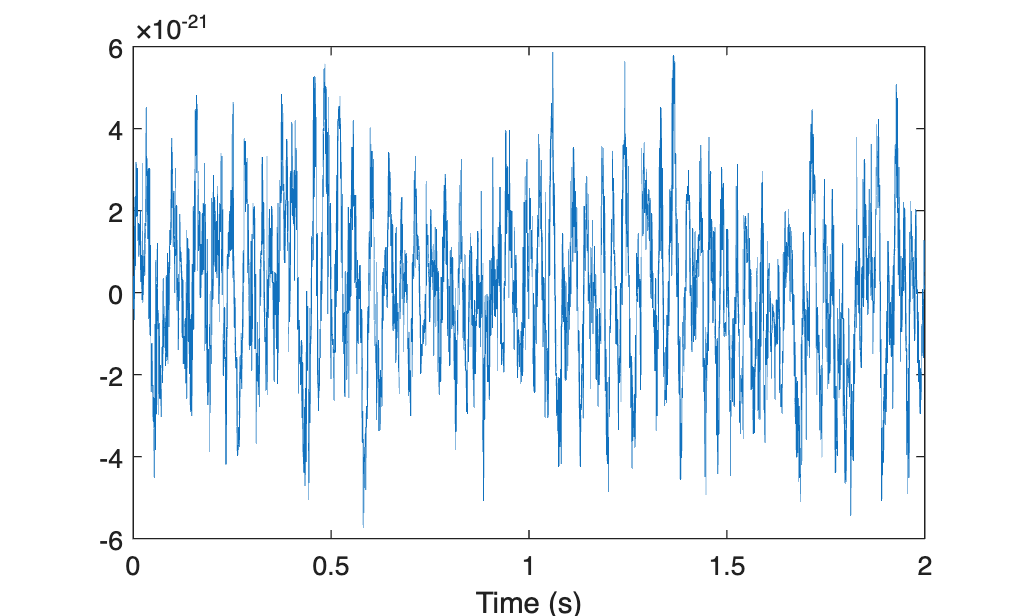

timeVectorAnalysis = 0:dt:datalen-dt;
figure;
plot(timeVectorAnalysis, analysis.dataVec);
xlabel('Time (s)');

I can see some differences in the raw time series, but I will do some PSO to decide the paramiters of a possible signal as well as finding whether there is a signal at all. 

To decide wether there is a signal I will run my PSO code on both my test data and the data I know to be clean. So I will first take a bunch of PSO runs of the training data (this is the training process).

a1_min = 40;
a2_min = 1;
a3_min = 1;
a1_max = 100;
a2_max = 50;
a3_max = 15;

nSamples = length(training.trainData);
kNyq = floor(nSamples/2)+1;
posFreq = (0:(kNyq-1))*(1/datalen);
psdPosFreq = noisePSD(posFreq);

params = struct();
params.dataY = training.trainData;           % Training data (noise only)
params.dataX = timeVector;                   % Time vector
params.dataXSq = timeVector.^2;              % Time squared
params.dataXCb = timeVector.^3;              % Time cubed
params.psd = psdPosFreq;                     % PSD at positive frequencies
params.sampFreq = training.sampFreq;         % Sampling frequency
params.rmin = [a1_min, a2_min, a3_min];      % Lower bounds
params.rmax = [a1_max, a2_max, a3_max];      % Upper bounds
fitFuncHandle = @(x) glrtqcsig4pso(x, params);
ndims = 3;
psoParams = struct();
nruns = 10; % number of training runs 
psoParams.maxSteps = 500; % much lower than actual fitting because we know there is no signal
parfor runIdx = 1:nruns
    psoOut = crcbpso(fitFuncHandle, ndims, psoParams, 2);
    allRuns(runIdx).fitness = psoOut.bestFitness;
    allRuns(runIdx).location = psoOut.bestLocation;
    [~, allRuns(runIdx).params] = fitFuncHandle(psoOut.bestLocation);
    disp(psoOut.bestFitness);
end

  -6.0656e+16

  -8.2901e+15

  -1.3298e+17

  -1.9517e+15

  -4.4994e+15

  -5.2714e+15

  -9.0983e+15

  -2.6573e+16

  -8.8996e+16

  -3.1024e+15



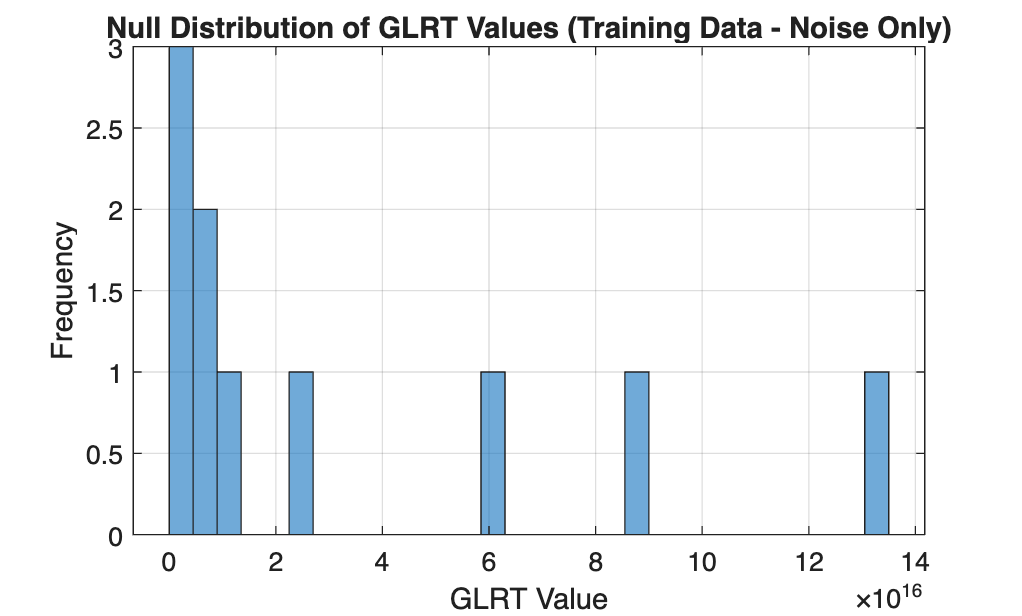

training_GLRT = -[allRuns.fitness];
figure;
histogram(training_GLRT, 30);
xlabel('GLRT Value');
ylabel('Frequency');
title('Null Distribution of GLRT Values (Training Data - Noise Only)');
grid on;

Now I have a distribution of GLRT values of 

This is the final project of the stat methods where we search for a signal in some data. First I will look at the training data.

training = load("TrainingData.mat");
% training is a struct containing data and sampFreq
dt = 1/training.sampFreq;
datalentrain = length(training.trainData)/training.sampFreq;
timeVector = 0:dt:datalentrain-dt;
idx = timeVector <= 2; % plotting two seconds to compare to analysis data
figure;
plot(timeVector(idx),training.trainData(idx)); % look at the raw training data
xlabel('Time (s)');
title('Raw Training Data');

The next thing we'll do is generate the periodgram and generate the PSD. 

[ppx,f] = pwelch(training.trainData, 128, [], [], training.sampFreq);
noisePSD = @(freq) interp1(f, ppx, freq, 'linear', 'extrap');
figure;
plot(f,ppx);
xlabel('Frequency (Hz)');
title('Power Spectral Density of Training Data');

The PSD looks like a partial gaussian with a long tail at highter frequencies. 

Next I will start to look at the analysis data.

analysis = load("analysisData.mat");
dt = 1/training.sampFreq

dt = 9.7656e-04

datalen = length(analysis.dataVec)/training.sampFreq

datalen = 2

timeVectorAnalysis = 0:dt:datalen-dt;
figure;
plot(timeVectorAnalysis, analysis.dataVec);
xlabel('Time (s)');

I can see some differences in the raw time series, but I will do some PSO to decide the paramiters of a possible signal as well as finding whether there is a signal at all. 

To decide wether there is a signal I will run my PSO code on both my test data and the data I know to be clean. So I will first take a bunch of PSO runs of the training data (this is the training process).

null_dist_file = 'MDC/null_dist.mat'

null_dist_file = 'MDC/null_dist.mat'


if isfile(null_dist_file)
    fprintf('Loading pre-computed null distribution from %s...\n', null_dist_file);
    load(null_dist_file, 'training_GLRT', 'psdPosFreq', 'posFreq');
    fprintf('Null distribution loaded successfully! (%d training runs)\n', length(training_GLRT));
else
    fprintf('No saved null distribution found. Generating new one...\n');
    
    % Define search ranges
    a1_min = 40;
    a2_min = 1;
    a3_min = 1;
    a1_max = 100;
    a2_max = 50;
    a3_max = 15;
    
    nSamples = length(training.trainData);
    kNyq = floor(nSamples/2)+1;
    posFreq = (0:(kNyq-1))*(1/datalentrain);
    psdPosFreq = noisePSD(posFreq);
    
    params = struct();
    params.dataY = training.trainData;           % Training data (noise only)
    params.dataX = timeVector;                   % Time vector
    params.dataXSq = timeVector.^2;              % Time squared
    params.dataXCb = timeVector.^3;              % Time cubed
    params.psd = psdPosFreq;                     % PSD at positive frequencies
    params.sampFreq = training.sampFreq;         % Sampling frequency
    params.rmin = [a1_min, a2_min, a3_min];      % Lower bounds
    params.rmax = [a1_max, a2_max, a3_max];      % Upper bounds
    
    fitFuncHandle = @(x) glrtqcsig4pso(x, params);
    ndims = 3;
    psoParams = struct();
    nruns = 1000; % number of training runs 
    psoParams.maxSteps = 500; % much lower than actual fitting because we know there is no signal
    
    fprintf('Running %d training runs (this will take a while)...\n', nruns);
    parfor runIdx = 1:nruns
        psoOut = crcbpso(fitFuncHandle, ndims, psoParams, 2);
        allRuns(runIdx).fitness = psoOut.bestFitness;
        allRuns(runIdx).location = psoOut.bestLocation;
        [~, allRuns(runIdx).params] = fitFuncHandle(psoOut.bestLocation);
    end
    
    training_GLRT = -[allRuns.fitness];
    
    % Save the null distribution for future use
    save(null_dist_file, 'training_GLRT', 'psdPosFreq', 'posFreq');
    fprintf('Null distribution saved to %s\n', null_dist_file);
end

Loading pre-computed null distribution from MDC/null_dist.mat...


Null distribution loaded successfully! (1000 training runs)


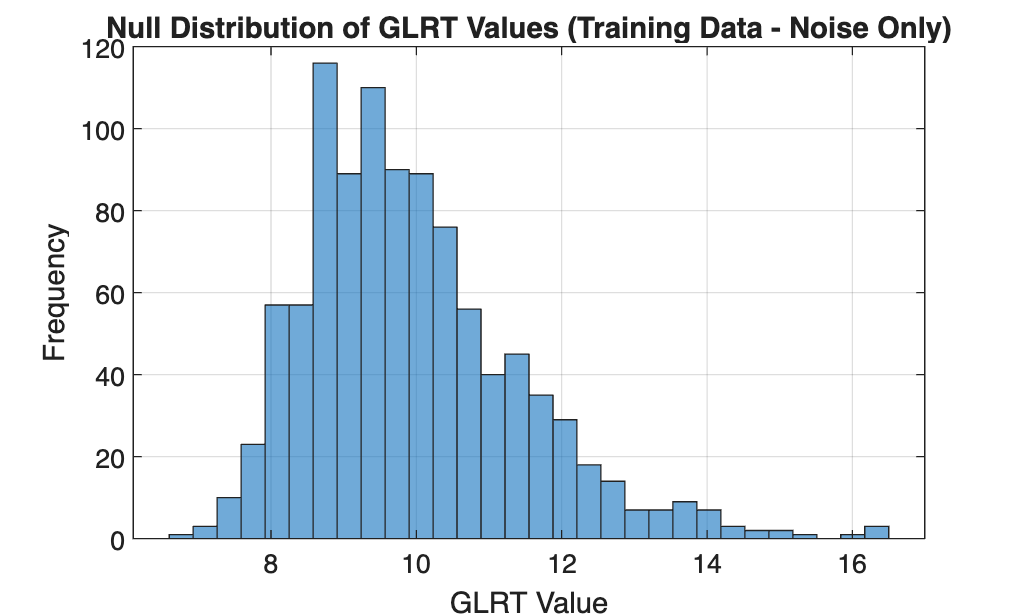


% Plot the null distribution (whether loaded or just created)
figure;
histogram(training_GLRT, 30);
xlabel('GLRT Value');
ylabel('Frequency');
title('Null Distribution of GLRT Values (Training Data - Noise Only)');
grid on;


% Display statistics
fprintf('========== Null Distribution Statistics ==========\n');

========== Null Distribution Statistics ==========


fprintf('Number of training runs: %d\n', length(training_GLRT));

Number of training runs: 1000


fprintf('Mean GLRT: %.4f\n', mean(training_GLRT));

Mean GLRT: 9.9474


fprintf('Std Dev: %.4f\n', std(training_GLRT));

Std Dev: 1.4803


fprintf('Min: %.4f, Max: %.4f\n', min(training_GLRT), max(training_GLRT));

Min: 6.6586, Max: 16.4138


Now I have a distribution of GLRT values. By looking at the histagram I have decided to use a chi^2 distribution, as it seems to be more fitting than a 

a1_min = 40;
a2_min = 1;
a3_min = 1;
a1_max = 100;
a2_max = 50;
a3_max = 15;

nSamples = length(analysis.dataVec);
kNyq = floor(nSamples/2)+1;
posFreq = (0:(kNyq-1))*(1/datalen);
psdPosFreq = noisePSD(posFreq);

params = struct();
params.dataY = analysis.dataVec;           % Training data (noise only)
params.dataX = timeVectorAnalysis;                   % Time vector
params.dataXSq = timeVectorAnalysis.^2;              % Time squared
params.dataXCb = timeVectorAnalysis.^3;              % Time cubed
params.psd = psdPosFreq;                     % PSD at positive frequencies
params.sampFreq = training.sampFreq;         % Sampling frequency
params.rmin = [a1_min, a2_min, a3_min];      % Lower bounds
params.rmax = [a1_max, a2_max, a3_max];      % Upper bounds
fitFuncHandle = @(x) glrtqcsig4pso(x, params);
ndims = 3;
psoParams = struct();
nruns = 10; % number of training runs 
psoParams.maxSteps = 2000; % much lower than actual fitting because we know there is no signal
allRunsAnalysis = struct('fitness', cell(1, nruns), ...
                         'location', cell(1, nruns), ...
                         'params', cell(1, nruns));
parfor runIdx = 1:nruns
    psoOut = crcbpso(fitFuncHandle, ndims, psoParams, 2);
    allRunsAnalysis(runIdx).fitness = psoOut.bestFitness;
    allRunsAnalysis(runIdx).location = psoOut.bestLocation;
    allRunsAnalysis(runIdx).params = psoOut.bestLocation;  % ← Just store the location (parameters)
    disp(psoOut.bestFitness);
end

  -23.3132

  -29.5293

  -27.9036

  -31.8277

  -31.8000

  -29.4211

  -31.8048

  -32.3110

  -30.7757

  -23.0248



training_GLRT = -[allRuns.fitness];
% Find the best run from the 8 analysis runs
[bestOverallFitness, bestOverallRun] = min([allRunsAnalysis.fitness]);
bestOverallParams = allRunsAnalysis(bestOverallRun).params;
best_analysis_GLRT = -bestOverallFitness;

% Signifigance calculation

null_mean = mean(training_GLRT);
null_std = std(training_GLRT);
df_est = 2 * null_mean^2 / null_std^2;  % Method of moments
p_value_chi2 = 1 - chi2cdf(best_analysis_GLRT, df_est);
sigma_value = norminv(1 - p_value_chi2);

% Display results
disp('========== PSO Analysis Results ==========');

========== PSO Analysis Results ==========


disp(['Signifigance: ', num2str(p_value_chi2)]);

Signifigance: 1.7831e-08


disp(['Sigma Value: ', num2str(sigma_value)]);

Sigma Value: 5.5111


disp(['Best run: ', num2str(bestOverallRun), '/', num2str(nruns)]);

Best run: 2/10


disp(['Best parameters found: [a1=', num2str(bestOverallParams(1)), ...
      ', a2=', num2str(bestOverallParams(2)), ...
      ', a3=', num2str(bestOverallParams(3)), ']']);

Best parameters found: [a1=0.2144, a2=0.53506, a3=0.63715]


disp(['Best fitness (negative GLRT): ', num2str(bestOverallFitness)]);

Best fitness (negative GLRT): -32.311


disp(['Maximum GLRT value: ', num2str(best_analysis_GLRT)]);

Maximum GLRT value: 32.311


disp('==========================================');

The signifigance of the alternitate hypothisys is very high—it is very likely that there is a signal. The estimated paramiters are reported above. 5 sigma is considered signifigant enough for a discovery, and I have ~5.5 sigma. Therefore I can be very confident about the presence of a signal.